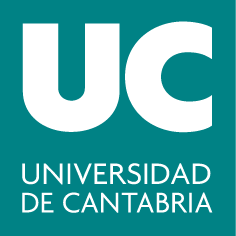

#### ***Grado en Ingeniería ****de Tecnologías de Telecomunicación*

## **G283: Cálculo II**

# **Práctica 4: Campos vectoriales**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Objetivos	

- Dibujar muestras de campos vectoriales en el plano.	

- Dibujar líneas de flujo y líneas equipotenciales sobre una muestra de un campo vectorial conservativo para entender sus propiedades.	

- Utilizar representaciones gráficas como apoyo para entender las definiciones y las propiedades de los campos escalares y vectoriales.

### Resumen teórico

#### Gradiente

Si $z=f(x,y,z)$ es una función de tres variables, se define el gradiente de $f$ como el campo vectorial: 


$$\vec{\nabla} f(x,y,z)=\frac{\partial f(x,y,z)}{\partial x}\vec{i}+\frac{\partial f(x,y,z)}{\partial y}\vec{j}+\frac{\partial f(x,y,z)}{\partial z} \vec{k}$$


#### Línea de fuerza o línea de flujo

Es una curva $\vec{r}(t)$ tal que $\vec{r'}(t)=\vec{F}(\vec{r}(t))$, es decir, $\vec{F}$ produce el campo de velocidades de la curva $\vec{r}(t)$. Geométricamente, el vector campo es tangente a la línea de fuerza en cada punto.

#### Líneas y superficies equipotenciales

Sea $\vec{F}=\nabla f(x,y)$, siendo $f(x,y)$ diferenciable. Las líneas equipotenciales de $\vec{F}$ son las curvas que verifican $f(x,y)=C$.

Sea $\vec{F}=\nabla f(x,y,z$), siendo $f(x,y,z)$ diferenciable. Las superficies equipotenciales de $\vec{F}$ son las superficies que verifican $f(x,y,z)=C$.

Las líneas equipotenciales y las superficies equipotenciales son perpendiculares a las líneas de fuerza.

### Comandos útiles

#### Comandos para calcular numéricamente el gradiente de un campo escalar

- `[fx, fy, fz]=gradient(f)`: Calcula el gradiente de un campo escalar $f(x,y,z)$. Tendrá tantas componentes como las variables de las que dependa la función $f(x,y,z)$; en este caso tres. Ejemplo:

v=-2:0.2:2;
[x,y]=meshgrid(v);
f=x.*exp(-x.^2-y.^2);
[fx,fy]=gradient(f);

#### Comandos para representar vectores

- `quiver(X, Y, U, V): `Dibuja los vectores escalados de componentes U, V con flechas que tienen su origen en los puntos de coordenadas X, Y. Las matrices X, Y, U, V deben tener el mismo tamaño. Si se añade como quinto argumento 0, los vectores que se representan no se escalan, es decir, la longitud de las flechas es el valor real del módulo de los vectores. Ejemplo:

[X,Y]=meshgrid(-1:0.5:1); 
U=Y+X;V=-X+Y; % Componentes del vector 
quiver(X,Y,U,V)
quiver(X,Y,U,V,0)

#### Otros comandos para representaciones gráficas

- `surf(X,Y,Z,C)`: Representa el gráfico de superficie de la función $z=f(x,y)$ con los colores especificados en C (este último parámetro se puede ignorar).

- `contour(X,Y,Z,n): `Representa el gráfico de contorno (curvas de nivel) para la matriz Z usando `n` líneas.

- `axis([a,b,c,d])`: Fija las dimensiones de la ventana del gráfico que está abierto, considerando $x \in [a,b]$ e $y\in [c,d]$.

- `legend(``'``string1``'``,``'``string2``'``,``'``string3``'``,…)`: Identifica ordenadamente las características de varias gráficas representadas sobre una figura con los nombres asignados en las cadenas de caracteres: string1, string2, string3, etc.

###  Ejercicios resueltos

**1. Líneas de fuerza o líneas de flujo de un campo vectorial **$F$**conocida su ecuación explícita **$y=LF(x,k)$ ó $x=LF(y,k)$

a) Dado el campo vectorial $\vec{F}(x,y)=(2x,y)$, representar una muestra del campo vectorial y añadir a la figura las líneas de fuerza de ecuación $x=ky^2$, en el cuadrado $[-4,4] \times [-4,4]$, tomando  $k = -1:0.1:1$.

b) Dado el campo vectorial $\vec{F}(x,y)=(x,3y)$, representar una muestra del campo vectorial y añadir a la figura las líneas de fuerza de ecuación $y=kx^3$, en el cuadrado $[-4,4]\times[-4,4]$, tomando $k = -0.6:0.05:0.6$.

a) Dado el campo vectorial $\vec{F}(x,y)=(2x,y)$, representar una muestra del campo vectorial y añadir a la figura las líneas de fuerza de ecuación $x=ky^2$, en el cuadrado $[-4,4] \times [-4,4]$, tomando  $k = -1:0.1:1$.

x=-4:.5:4; y=-4:.5:4;
[X,Y]=meshgrid(x,y); % malla sobre la que se dibujará 
U=2*X; % primera componente del campo
V=Y; % segunda componente del campo
figure(1)
quiver(X,Y,U,V,'r') % dibujo de los vectores escalados en rojo
axis equal; grid on
title('campo vectorial F=(2x,y) escalado')
hold on
% dibuja las líneas de fuerza en azul
y=-4:.1:4;
for k=-1:0.1:1
   x=k*y.^2;
   plot(x,y,'b')
   hold on
end
axis([-4 4 -4 4]) %fija el marco de la ventana
title('Muestra del campo y Líneas de fuerza del campo F=(2x,y)')
hold off

b) Dado el campo vectorial $\vec{F}(x,y)=(x,3y)$, representar una muestra del campo vectorial y añadir a la figura las líneas de fuerza de ecuación $y=kx^3$, en el cuadrado $[-4,4]\times[-4,4]$, tomando $k = -0.6:0.05:0.6$.

x=-4:.5:4; y=-4:.5:4;
[X,Y]=meshgrid(x,y); % malla sobre la que se dibujará 
U=X; % primera componente del campo
V=3*Y; % segunda componente del campo
figure(2)
quiver(X,Y,U,V,'r') % dibujo de los vectores escalados en rojo
axis equal; grid on
title('campo vectorial F=(x,3y) escalado')
hold on
% dibuja las líneas de fuerza en azul
x=-4:.1:4;
for k=-0.6:0.05:0.6
   y=k*x.^3;
   plot(x,y,'b') 
   hold on
end
axis([-4 4 -4 4]) %fija el marco de la ventana
title('Muestra del campo y líneas de fuerza del campo F=(x,3y)')
hold off

**2. Líneas de fuerza o líneas de flujo de un campo vectorial **$F$**conocida su ecuación implícita **$LF(x,y)=k$

Dado el campo escalar $f(x,y)=xy$, se pide:

a) Representa el campo escalar $f(x,y)$.

b) Calcular el gradiente y hacer una representación del campo vectorial gradiente, las líneas de flujo del gradiente cuya ecuación es $x^2-y^2=C$ y las curvas de nivel o equipotenciales de ecuación $xy=k$. Haz la representación en el cuadrado $[-4,4]\times[-4,4]$.

a) Representa el campo escalar $f(x,y)$.

x=-4:.5:4; y=-4:.5:4;
[X,Y]=meshgrid(x,y); % malla sobre la que se dibujará 
Z=X.*Y; % valores del campo escalar
figure(3)
surf(X,Y,Z) % dibujo de la superficie z=f(x,y)=xy
shading interp
title('Campo escalar f(x,y)=xy')

b) Calcular el gradiente y hacer una representación del campo vectorial gradiente, las líneas de flujo del gradiente cuya ecuación es $x^2-y^2=C$ y las curvas de nivel o equipotenciales de ecuación $xy=k$. Haz la representación en el cuadrado $[-4,4]\times[-4,4]$.

% Cálculo del gradiente
[GX,GY]=gradient(Z); 
figure(4)
quiver(X,Y,GX,GY,'r') % dibujo del gradiente en rojo
axis equal; grid on
hold on

% Dibuja las líneas de flujo del campo gradiente (x^2-y^2=k)
LF=X.^2-Y.^2;
contour(X,Y,LF,10,'b') % dibujo de 10 líneas de flujo en azul

% Dibujo de 10 curvas de nivel del campo escalar (equipotenciales)
contour(X,Y,Z,10, 'k') % se pueden especificar ciertos valores de k: contour(X,Y,Z,[1 2 3], 'k') 
axis([-4 4 -4 4])
 
title('campo vectorial grad(f)=(y,x);líneas de flujo de grad(f); curvas de nivel de f')
legend('Campo vectorial','líneas de flujo','curvas de nivel')
hold off